This lesson is based off of the following notes:[https://www.astro.princeton.edu/~gk/A403/polytrop.pdf](https://www.astro.princeton.edu/~gk/A403/polytrop.pdf)

The purpose of this document is to study polytropes. They serve as crude models of stars. They are self-gravitating gaseous shperes. They cannot simulate the behaviour of a star but will serve to illustrate how a large sphere gravitates. We will be observing plots of the different polytropic indices and the steps along the way. The goal of these MATLAB-simulink assisted tutorials is the ability to visualise how things change with graphs. Polytropes in particular have the property that only some parts can be sovled analytically, we will therefore chime in with plotted numerical solutions to visualise. We begin by assuming that they are in hydrostatic equilibrium, from which we can describe using two first order differential equations. Please have the notes that this is based off of handy. Not every important bit of information is listed here. 


$$\frac{dP}{dr}=\frac{GM_{r}}{r^{2}}\rho$$
        

and


$$\frac{dM_{r}}{dr}=4\pi r^{2}\rho$$


The former is describing the change in pressure as a function of mass contained in the radius, the radius and the density of the object. The latter describes how much mass if contained in the given radius. To visualize these quantities,  let's go ahead and plot them. We will plot a series of diffrent density values to observe its effect.

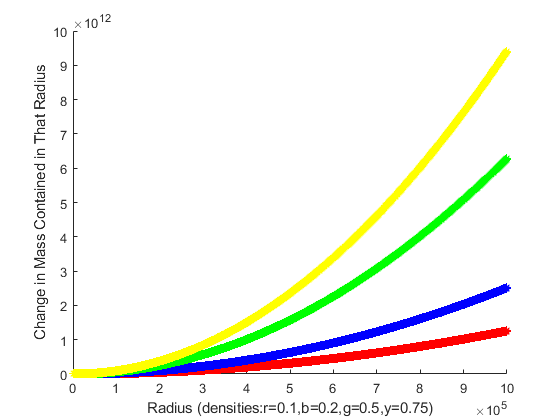

%we must begin with the differential equation for mass as a function of
%radius. There will be pauses in here to see graphs, proceed past them with
%a keystroke.
close all
clear all
%this will fill our structure array with the data that we need
counter=1;
for density=[0.1 0.2 0.5 0.75]
    for i=1:1000:1000000
        mass(counter).dMr_dr(i,1)=i;
        mass(counter).dMr_dr(i,2)=4*(3.14159)*(i.^2)*density;
    end
    counter=counter+1;
end

hold on 
plot(mass(1).dMr_dr(:,1),mass(1).dMr_dr(:,2),'r*')
plot(mass(2).dMr_dr(:,1),mass(2).dMr_dr(:,2),'b*')
plot(mass(3).dMr_dr(:,1),mass(3).dMr_dr(:,2),'g*')
plot(mass(4).dMr_dr(:,1),mass(4).dMr_dr(:,2),'y*')
xlabel('Radius (densities:r=0.1,b=0.2,g=0.5,y=0.75)')
ylabel('Change in Mass Contained in That Radius')
hold off 
pause(1)

close gcf

Clearly we see a simple r^2 relationship that is scaled by the density. We can now go ahead and perform some algebra, differentiate the first differential equation with respect to r and subsitute in the second to obtain a second order poisson equation.


$$\frac{1}{r^{2}}\frac{d}{dr}(\frac{r^{2}}{\rho}\frac{dP}{dr})=-4\pi G \rho$$


We now assume a polytropic relation between pressure and density


$$P=K\rho^{1+\frac{1}{n}}$$


K and n are real and positive constants, n is the plolytropic index. We introduce some dimentionless variables.


$$\rho=\rho_{c}\theta^{n}$$
     
$$P=P_{c}\theta^{n+1}$$
   
$$r=\alpha\xi$$


Alpha is a constant which is constructed from a host of variables. See the paper this is based off of to observe these quantities and understand their meanings here. The purpose of this is to obtain our equation in dimensionless variables as follows(Known as the Lane-Emden equation):


$$\frac{1}{\xi^{2}}\frac{d}{d\xi}(\xi^{2}\frac{d\theta}{d\xi})=-\theta^{n}$$


With initial conditions $\theta = 1$ and $\frac{d\theta}{d\xi}=0$ at $\xi=0$.

It is important to note that $\theta
$ ranges from 1 at the core to 0 at the surface, that will be the boundary for our plots. 

Now that we have established a differential equation and its solutions, let's plot them. The case where n==0, we will have an incompressible fluid. See the notes attached to this code to see the formula from each case or read it from the code.

%the case where n==0

%a function of the variable xi
for i=0:0.0001:10
    xi(counter,1)=i;
    xi(counter,2)=1-((i.^2)./6);
    if xi(counter,2)<0
        break
    end
    counter=counter+1;
end
hold on
plot(xi(:,1),xi(:,2),'r*')
xlabel('Xi(blue n==1, red n==0)')
ylabel('Theta ')
pause(1)

The corresponding (n==0) density is constant and the corresponding pressure is linear. This is a rough approximation to a rocky planet like Earth for example. Next we can observe the next analytic solution which is the n==1 case. We will plot this on top of the previous case in order to observe the differences. 

for i=0.001:0.0001:10
    xi_1(counter,1)=i;
    xi_1(counter,2)=sin(i)./i;
    if xi_1(counter,2)<0
        break
    end
    counter=counter+1;
end
plot(xi_1(:,1),xi_1(:,2),'b*')
pause(1)

This is quite interesting as the behaviour of these two polytropes is very similar below Xi==1. For the Xi==1 case, the density scales linearly from the core density to the surface and the pressure scales as second order from the core to the surface of our polytrope. Before handing the solving of these ODE's to our iterative solver, let's take a look at the infinite radius  case of a polytrope. This is true for any polytrope with an index higher than five.

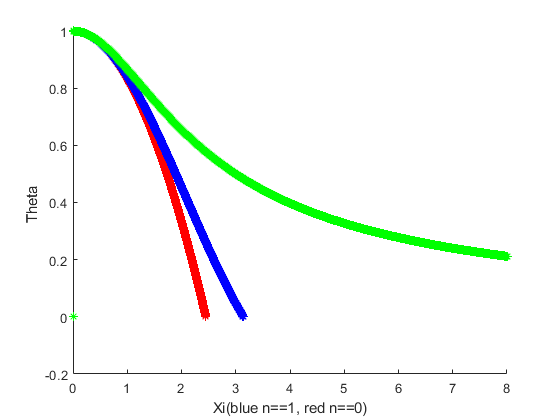

for i=0.001:0.0001:8
    xi_2(counter,1)=i;
    xi_2(counter,2)=1/(sqrt(1+((i.^2)/3)));
    if xi_2(counter,2)<0
        break
    end
    counter=counter+1;
end
plot(xi_2(:,1),xi_2(:,2),'g*')
hold off

pause(1)
close gcf

It is clear here that we will only approach 0 in the limit as $\xi$ goes to infinity, hence the infinite radius for this index of polytrope. We are now interested in solving for the cases where there exists a non analytic solution to the problem. This is ofcourse a non-issue with modern differential equation solvers in our hands. In fact, it is a staggeringly small amount of math and coding to get a solution to this system.

A few notes on numerically solving differential equations:

- We must reduce all N degree equations into N first degree equations.

- Differential equation solving is an iterative process, as each iterations passes the error from the truth will increase. 

- There are more advanced ways than the one illustrated here. Here the RK method is being used, but the Bulirsch-Stoer method can be used as well.

Let's get started by re-writing our second order ode as two first order ones(it's irritating because we started with this. We want to model this on the scale of the other three, so we'll need to perform this operation on the Lane-Emden equation). Don't let the Lane-Emden equation scare you. Simply expand it using the product rule to obtain:


$$\xi^{2}\frac{d^{2}\theta}{d\xi^{2}}+2\xi\frac{d\theta}{d\xi}=-\theta^{n}\xi^{2}$$


And then create a system of equations to obtain the following: 


$$\frac{d^{2}\theta}{d\xi^{2}}=-\theta^{n}-\frac{2}{\xi}\frac{d\theta}{d\xi}$$


We must now change the domain to be >0. Let's go ahead and code these.

%this is setting up our ODE solver. See the odefcn function to inspect the
%function which is going to be solved here. 

n=1.5; %specify the polytropic index
ic=[1 0]; %specify the initial conditions
tspan=[0.001 8] %interval, remeber, we have problems at zero. 

tspan =     0.0010    8.0000


[t,y] = ode45(@(t,y) odefcn(t,y,n), tspan, ic);
hold on 
plot(t,y(:,1),'r*')

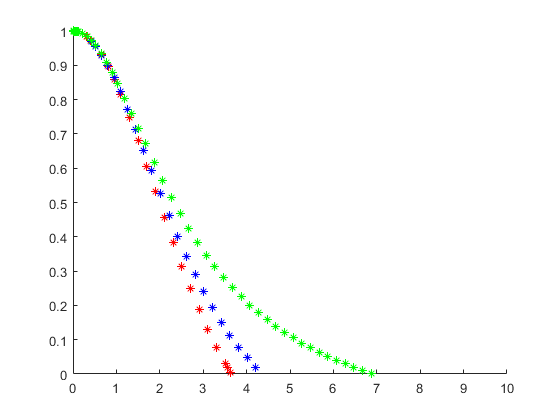

xlim([0 10])
ylim([0 1])
pause(1)
%let' now go ahead and solve a couple more cases and plot them
n=2; %specify the polytropic index 
[t1,y1] = ode45(@(t,y) odefcn(t,y,n), tspan, ic);
plot(t1,y1(:,1),'b*')
pause(1)
%now how about n==3
n=3; %specify the polytropic index
[t2,y2] = ode45(@(t,y) odefcn(t,y,n), tspan, ic);
plot(t2,y2(:,1),'g*')
hold off

pause(1)

It is evident here that these numerically solved curves fall inside of the above draw curves defined by analytic functions. This leads us to believe that our differential solver has done an adequate job. 

The purpose of all the above math is to determine $\xi_{1}$. This parameter is the value where $\theta=0$. For some cases, we could have analytically solved for this, which we did, and the rest is determined numerically. With this value, we can model the radius of different stars as a function of their $\xi_1$,$\rho_c$ and the polytropic index. To begin, let's examine the effect of polytropic index on radius of the polytrope.  The radius is obtained by the following:


$$R=\sqrt{\frac{K}{G}\frac{n+1}{4\pi}}\rho_{c}^{\frac{1-n}{2n}}\xi_{1}$$


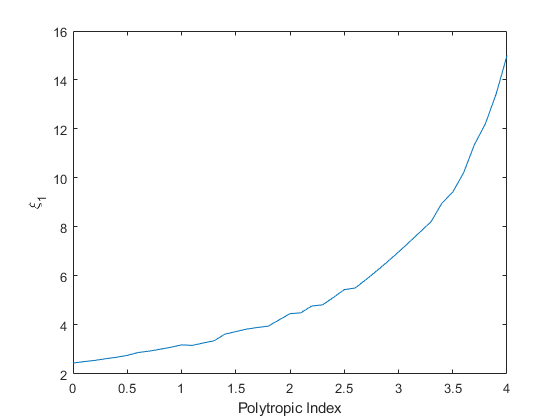

%radius=radfun(n,xi_one);
%we are using this function to abstract the above equation a bit an make it
%nicer to call inside of the upcoming loop. We now want to compute the
%effect of the polytropic index on the radius. In order to complete this
%task, we are going to iteratively solve for the xi_one values which correspond
%to n values from 0-5. I will determine the value at steps of 0.1 as we do
%not want to spend too much time solving ODE's.
tspan=[0.001 15];
dataVault(40,3)=zeros();
i=1;
for n=0:0.1:4.0
    tspan=[0.001 3*n+3];
    %solve the ode
    [tt(i).val(:,:),yy(i).val(:,:)] = ode45(@(t,y) odefcn(t,y,n), tspan, ic); 
    %find the value closest to 0(it may not find exactly the zero val)
    [~,idx]=min(abs(0-(yy(i).val(:,1))));
    %save this value in our dataVault.
    dataVault(i,2)=real(tt(i).val(idx,1));
    dataVault(i,1)=n;
    dataVault(i,3)=real(yy(i).val(idx,2));%this is for later on
    i=i+1;
end
plot(dataVault(:,1),dataVault(:,2))
xlabel('Polytropic Index')
ylabel('\xi_1')
pause(2)

close gcf

Just as we expected a second order differential equation would yield us, something resembling a parabola. I have stopped after the fourth polytropic index as we start to move towards infinit very quickly as we approach 5. We can now plug in these polytropic indices and equivalent $\xi_1$ to obtain the radii which we are searching for. 

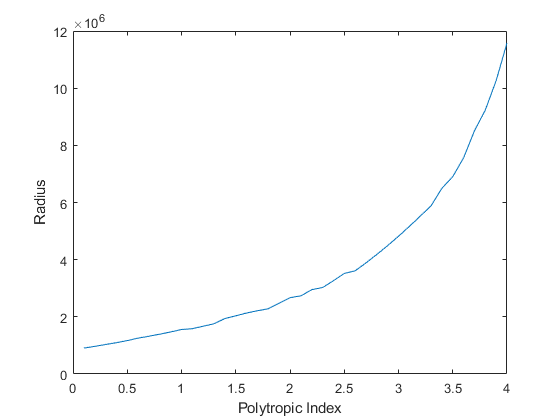

for gg=1:length(dataVault(:,1))
radius(gg)=radfun(dataVault(gg,1),dataVault(gg,2),10.^2);
end
plot(dataVault(:,1),radius(:))
xlabel('Polytropic Index')
ylabel('Radius')
pause(2)

Just as we expect, the radius curve has the same shape as the $\xi_1$ curve. In the radfun, we have set the central density to be constant. We now want to start the interesting part of this lesson where we are going to look at the radius of the star as we change the density and polytropic index together and make a 'heat map' of these.  We simply need to calculate the radius with variable pressure. 

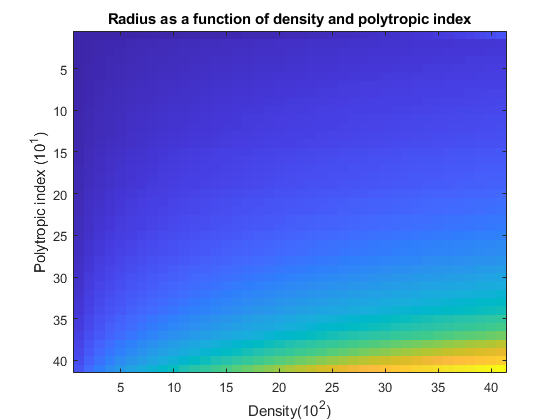

kk=1;
for density=100:100:4100
    for gg=2:length(dataVault(:,1))
        radius(gg,kk)=radfun(dataVault(gg,1),dataVault(gg,2),density);
    end
    kk=kk+1;
end
imagesc(radius)
xlabel('Density(10^2)')
ylabel('Polytropic index (10^1)')
title('Radius as a function of density and polytropic index')
pause(2)

close gcf

Clearly here, we can observe the effects of polytropic index and density has on the effect of radius of the polytrope. This is what we expected from the equations which govern polytropes. The purpose of this is to visualise the reuslt to make this intuitive. The next parameter that we want to observe from our polytrope model is the mass of the object. This is derived in the accompanying paper and the result is as follows:


$$M=4\pi(\frac{K}{G}\frac{n+1}{4\pi})^{\frac{3}{2}}\rho^{\frac{3-n}{2n}}_c[-\xi^{2}\frac{d\theta}{d\xi}]_{\xi=\xi_1}$$


This may not look particularily appealing to plot, but fortunately computers are powerful tools when we require the computation of derivatives or integrals. Further fortune, we only require the value of the derivative at a cetain point, which happens to be the point where we cross over the x-axis. We will compute the slope from the two points which are closest to the x-axis. We already have these points when we solved for $\xi_1$, since this is a second order ODE, we had to compute these points in order to inch forward, we can grab them from the diffetential equations we solved already. Our data vault has been filled. Let's go ahead and plot these.

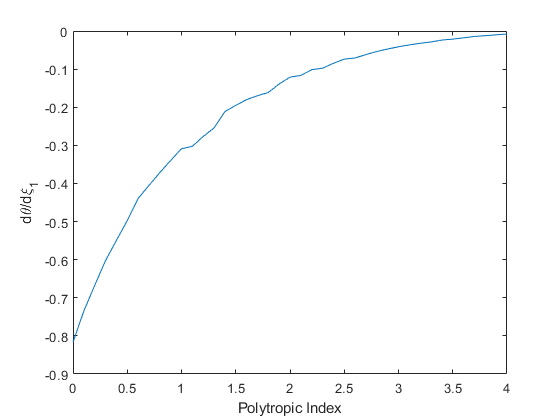

%plotting the d\theta/d\xi
plot(dataVault(:,1),dataVault(:,3))
xlabel('Polytropic Index')
ylabel('d\theta/d\xi_1')
pause(2)

close gcf

The first question we always ask is: does this plot make sense? Well taking a look at the plot of $\theta(\xi)$, as we approach five, we will never cross the x-axix, which corresponds to the slope approaching zero as polytropic index goes to five. Let's go ahead now and plot the mass as a function of central density($\rho_c$) and $\xi$. A function containing the mass function has been made.

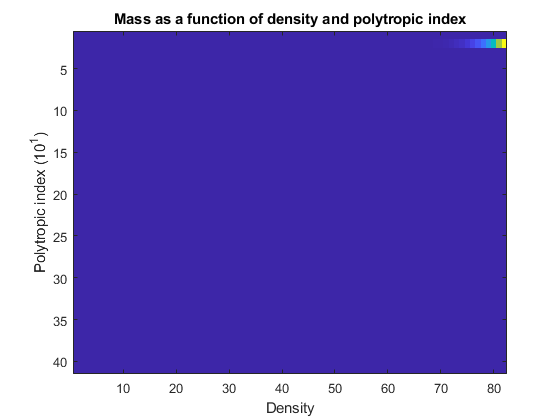

mass_vault(length(dataVault(:,1)),41)=zeros();
for density_2=100:100:4100
    for gg=2:length(dataVault(:,1))
        mass_vault(gg,kk)=massfun(dataVault(gg,1),dataVault(gg,3),dataVault(gg,2),density_2);
    end
    kk=kk+1;
end
%size(mass_vault)
%mass_vault=mass_vault(mass_vault==real(mass_vault));
imagesc(mass_vault)
xlabel('Density')
ylabel('Polytropic index (10^1)')
title('Mass as a function of density and polytropic index')
pause(2)

%close gcf